%   Made by Arslan, E4
%   
%   Version changelog:
%   V1 := Based on IRT_L8 only

zeta = 0.5169

Cmax = 1.1500

phase_margin = 53.1718

w_bw = 96.9143

mag = 0.0106

phase = -175.2751

wout = 96.9143

mag = -39.4740

Kp = 94.1236

mag = 1.0000

phase = -175.2751

wout = 96.9143

Td = 0.0206

G_PD =
 
  1.942 s + 94.12
 
Continuous-time transfer function.



Tf = 0.0034

result =
 
               226.6 s^2 + 9639 s + 9412
  ----------------------------------------------------
  0.003439 s^4 + 1.031 s^3 + 235.7 s^2 + 9659 s + 9424
 
Continuous-time transfer function.



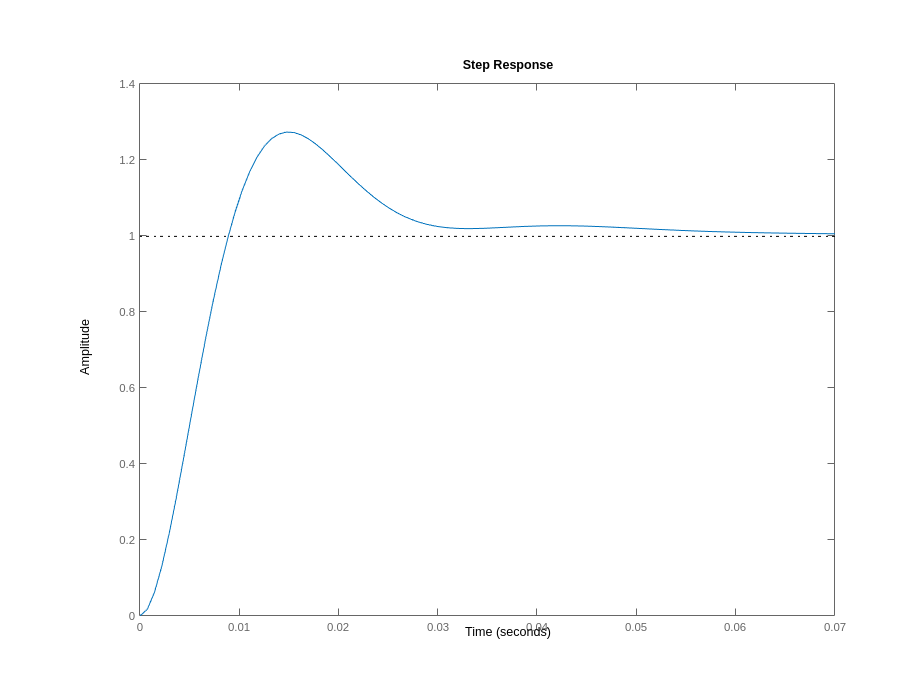

% testbench
s = tf('s');
G = (100 * (s+1)) / ((s+1) * (s+2) * (s+6));
Ts = 0.1;
OS = 15;


PIDSolver(G, Ts, OS)

% function code

function PIDSolver(G, Ts, OS, plotMode)
    s = tf('s');

    % Calculate zeta bode(G);grid on
    zeta = (-log(OS/100)) / (((pi^2 + log(OS/100)^2))^(1/2))
    
    % Calculate overshoot
    Cmax = (1 + exp(-((zeta*pi)/sqrt(1-zeta^2))))
    
    % Calculate fasemargin
    phase_margin = atan((2*zeta) / (-2*zeta^2 + (1+(4*zeta^4))^(1/2))^(1/2));
    phase_margin = rad2deg(phase_margin)
    
    % Calculate w_bw
    w_bw = (4/(Ts*zeta)) * (sqrt((1-(2*zeta^2))+sqrt((4*zeta^4) - (4*zeta^2) + 2)))

    % Bode 1
    [mag,phase,wout] = bode(G,w_bw)
    mag = mag2db(mag)

    % Make Kp
    Kp = abs(mag);
    Kp = db2mag(Kp)
    [mag,phase,wout] = bode(G*Kp,w_bw)

    % Make Td
    Td = 1/(w_bw/2)

    % Make G_PD
    G_PD = Kp * (1 + (s * Td))
    bode(G_PD);grid on

    % Make Tf
    Tf = 1/(w_bw*3)
    G_PD = Kp * (1 + (s * Td) / (s * Tf + 1));
    bode(G_PD); grid on

    % Make openloop plot of system
    G = G*G_PD;
    bode(G); grid on

    % Make stepresponse
    result = feedback(G,1)
    step(result);
end

